# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 01-Nov-2022 14:00:37

## Create Array of Layers

layers2 = [
    imageInputLayer([512 8 1],"Name","imageinput")
    convolution2dLayer([9 1],18,"Name","conv","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same","Stride",[2 2])
    convolution2dLayer([5 1],30,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    transposedConv2dLayer([2 2],30,"Name","transposed-conv","Cropping","same","Stride",[2 2])
    convolution2dLayer([5 1],30,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    transposedConv2dLayer([2 2],18,"Name","transposed-conv_1","Cropping","same","Stride",[2 2])
    convolution2dLayer([9 1],18,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([513 1],1,"Name","conv_4","Padding","same")
    regressionLayer("Name","regressionoutput")];

## Plot Layers

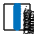

plot(layerGraph(layers));